**A Timeline of Interpolation: From Ancient Astronomy to Modern Signal and Image Processing**

Interpolation has been a cornerstone of scientific advancement, evolving from its early use in ancient astronomy to its modern applications in signal and image processing. Polynomial interpolation, in particular, plays a pivotal role in approximating complex functions through simpler polynomials. To explore this technique, I modeled a sinusoidal function and examined the effects of varying polynomial degrees on interpolation accuracy.

Interpolation originated in ancient times when astronomers sought to predict planetary positions. Over centuries, it expanded into engineering, physics, and computer science. Today, polynomial interpolation provides a way to approximate unknown data points with polynomials of varying degrees, balancing accuracy and generalizability.

In this experiment, I modeled a sinusoidal function as the underlying phenomenon to be approximated. Using MATLAB’s `polyfit` function, I computed polynomials of different degrees to fit the data. I then evaluated the performance of these polynomials over an in-sample range and an extended out-of-sample range to assess overfitting.

Lower-degree polynomials provided a broad approximation with visible errors, while higher-degree polynomials achieved greater accuracy in the sample range. However, overfitting became evident as the polynomial degree increased, leading to poor extrapolation performance out of sample.

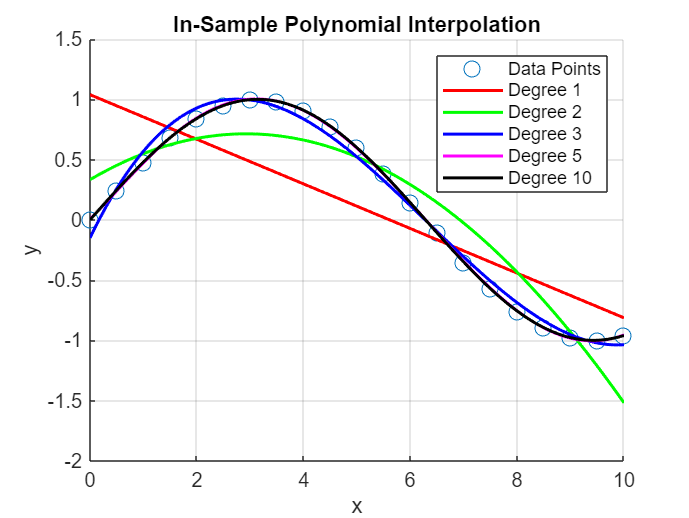

% Step 1: Initialize the data
x = 0:0.5:10; 
% I defined the x-values for the data points over the interval [0, 10], 
% representing the independent variable.

y = sin(x / 2); 
% I modeled the y-values using a sinusoidal function to represent the dependent variable.
% This function simulates a periodic phenomenon.

% Step 2: Compute polynomial coefficients for varying degrees
p1 = polyfit(x, y, 1); 
% I calculated the coefficients of a degree 1 polynomial (linear fit).
p2 = polyfit(x, y, 2); 
% I calculated the coefficients of a degree 2 polynomial (quadratic fit).
p3 = polyfit(x, y, 3); 
% I calculated the coefficients of a degree 3 polynomial (cubic fit).
p5 = polyfit(x, y, 5); 
% I calculated the coefficients of a degree 5 polynomial for a higher-accuracy approximation.
p10 = polyfit(x, y, 10); 
% I calculated the coefficients of a degree 10 polynomial to explore overfitting.

% Step 3: Define the grid for interpolation
zx = 0:0.1:10; 
% I defined a finer grid to evaluate the interpolated values, covering the same range as the original data.

% Step 4: Calculate interpolated values for each polynomial
zy1 = polyval(p1, zx); 
% I used the degree 1 polynomial to calculate y-values at the finer grid points.
zy2 = polyval(p2, zx); 
zy3 = polyval(p3, zx); 
zy5 = polyval(p5, zx); 
zy10 = polyval(p10, zx); 
% I repeated the process for polynomials of degrees 2, 3, 5, and 10.

% Step 5: Visualize interpolation within the sample range
figure; 
hold on;
plot(x, y, 'o', 'MarkerSize', 8); 
% I plotted the original data points to serve as a reference.
plot(zx, zy1, '-r', 'LineWidth', 1.5); 
% I plotted the degree 1 polynomial interpolation in red for comparison.
plot(zx, zy2, '-g', 'LineWidth', 1.5); 
plot(zx, zy3, '-b', 'LineWidth', 1.5); 
plot(zx, zy5, '-m', 'LineWidth', 1.5); 
plot(zx, zy10, '-k', 'LineWidth', 1.5); 
% I plotted higher-degree polynomial interpolations using different colors for clarity.

xlabel('x'); 
ylabel('y'); 
title('In-Sample Polynomial Interpolation'); 
legend('Data Points', 'Degree 1', 'Degree 2', 'Degree 3', 'Degree 5', 'Degree 10');
grid on;
hold off;


% Step 6: Evaluate performance out of sample
zx_out = -10:0.1:40; 
% I extended the range to test how the interpolated polynomials perform out of sample.

zy10_out = polyval(p10, zx_out); 
% I calculated the degree 10 polynomial values for the extended range.
p20 = polyfit(x, y, 20); 

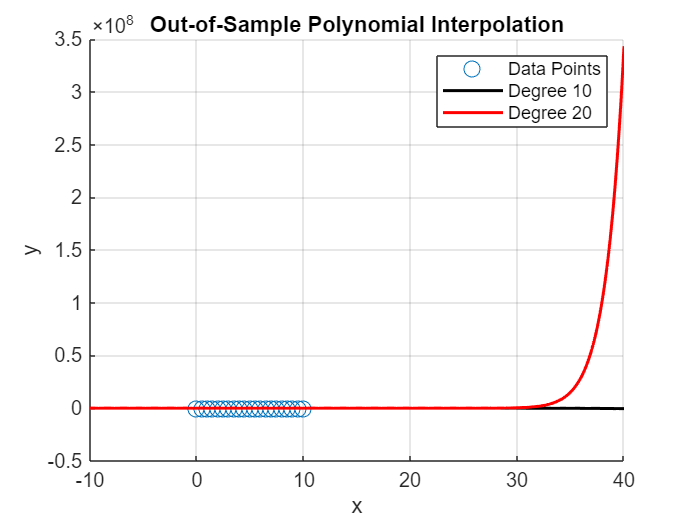

% I calculated a degree 20 polynomial to further explore overfitting.
zy20_out = polyval(p20, zx_out); 
% I calculated the degree 20 polynomial values for the extended range.

% Step 7: Visualize out-of-sample performance
figure; 
hold on;
plot(x, y, 'o', 'MarkerSize', 8); 
% I plotted the original data points for reference.
plot(zx_out, zy10_out, '-k', 'LineWidth', 1.5); 
% I plotted the degree 10 polynomial interpolation in the extended range.
plot(zx_out, zy20_out, '-r', 'LineWidth', 1.5); 
% I plotted the degree 20 polynomial interpolation in the extended range.

xlabel('x'); 
ylabel('y'); 
title('Out-of-Sample Polynomial Interpolation'); 
legend('Data Points', 'Degree 10', 'Degree 20');
grid on;
hold off;